# Lattice Filters

## Lattice Structures

A lattice filter is an example of an all-pass filter typically used the analysis and synthesis of speech signals.

### All-zero lattice structure  

An ***all-zero*** lattice models an FIR system.

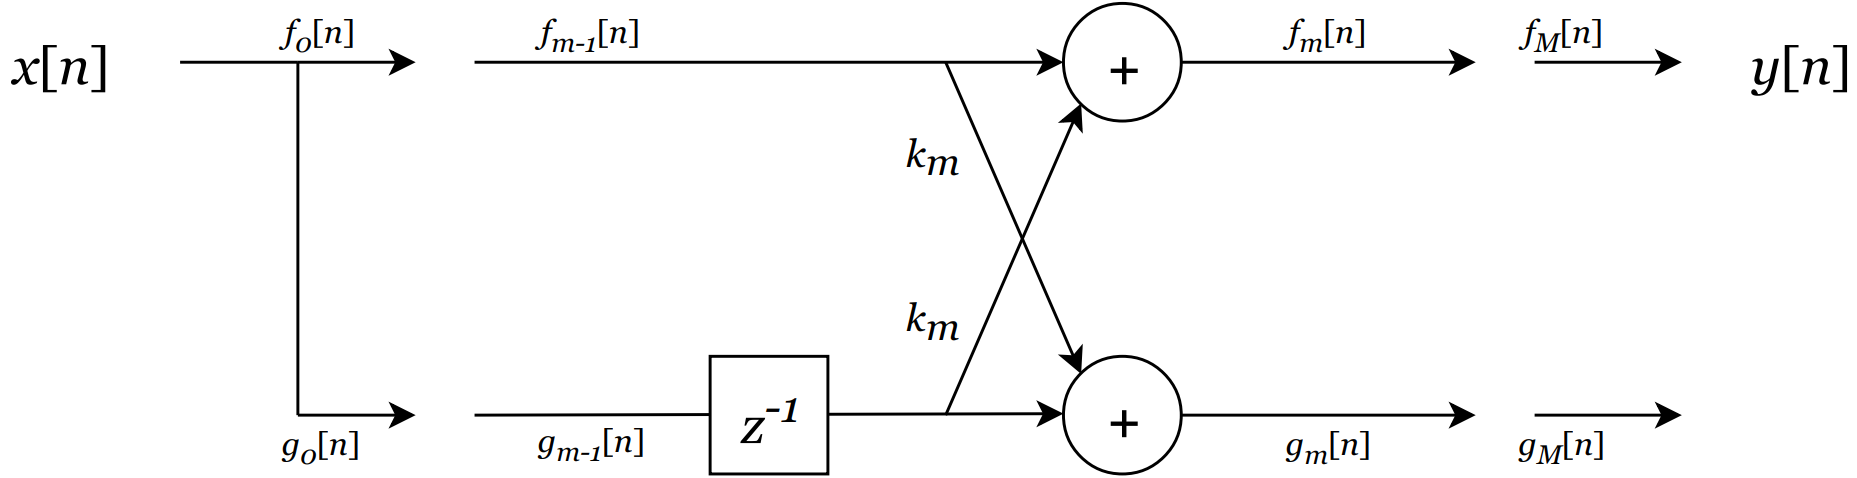

Each section has two inputs ($f_{m-1} \left\lbrack n\right\rbrack$ and $g_{m-1} \left\lbrack n-1\right\rbrack$) and two outputs $\left(f_m \left\lbrack n\right\rbrack ,g_m \left\lbrack n\right\rbrack \right)$. 

The $m$'th section/stage can be computed as follows:

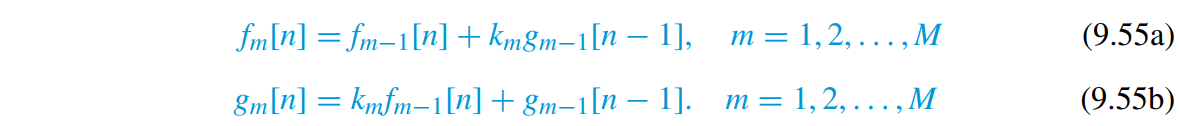

The overall system input and output are given by:

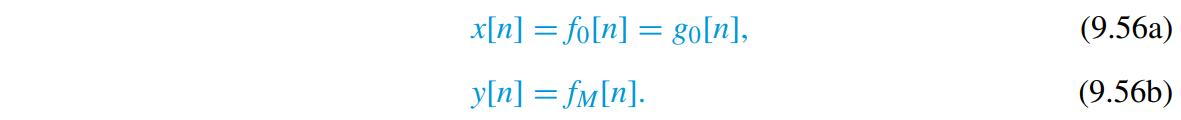

In general, the outputs of the *m*th section correspond to two FIR filters with the same coefficients but in reverse order:

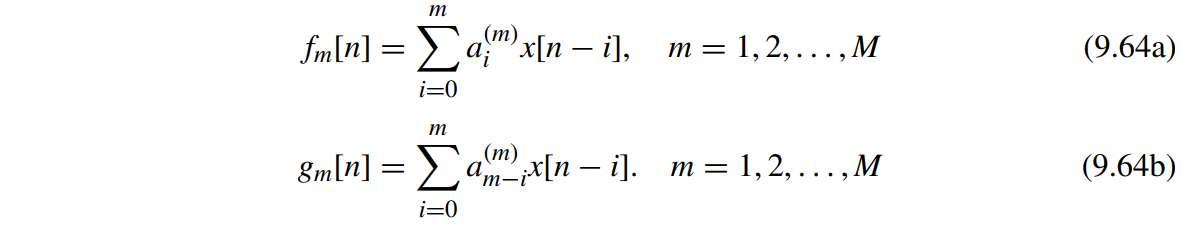

The system functions of these all-zero FIR filters are given by:

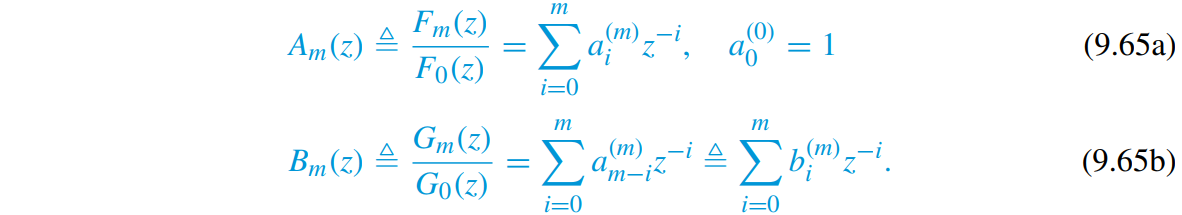

Suppose we have a FIR system of the form:


$$H\left(z\right)=\sum_{k=0}^M h\left\lbrack k\right\rbrack z^{-1}$$


We can start taking the z-transforms.

Since $z\left\lbrack n\right\rbrack =f_0 \left\lbrack n\right\rbrack =g_0 \left\lbrack n\right\rbrack$, taking the z-transform is straightforward:


$$X\left(z\right)=F_0 \left(z\right)=G_0 \left(z\right)$$


The difference equations of the $m$th section is:


$$\begin{array}{l}
f_m \left\lbrack n\right\rbrack =f_{m-1} \left\lbrack n\right\rbrack +k_m g_{m-1} \left\lbrack n-1\right\rbrack \\
g_m \left\lbrack n\right\rbrack =k_m \;f_{m-1} \left\lbrack n\right\rbrack +g_{m-1} \left\lbrack n-1\right\rbrack 
\end{array}$$


Taking the z-transform of the $m$th section gives us:


$$\begin{array}{l}
F_m \left(z\right)=F_{m-1} \left(z\right)+k_m G_{m-1} \left(z\right)z^{-1} \\
G_m \left(z\right)=k_m F_{m-1} \left(z\right)+G_{m-1} \left(z\right)z^{-1} 
\end{array}$$


We can normalise these two z-transforms as follows:


$$A_m \left(z\right)=\frac{F_m \left(z\right)}{F_0 \left(z\right)}=A_{m-1} \left(z\right)+k_m B_{m-1} \left(z\right)z^{-1}$$



$$B_m \left(z\right)=\frac{G_m \left(z\right)}{G_0 \left(z\right)}=k_m A_{m-1} \left(z\right)+B_{m-1} \left(z\right)z^{-1}$$


By the way we normalise, we notice that $A_0 \left(z\right)=B_0 \left(z\right)=1$ because

$A_0 =\frac{F_0 \left(z\right)}{F_0 \left(z\right)}=1$ and $B_0 =\frac{G_0 \left(z\right)}{G_0 \left(z\right)}=1$

Because of the normalisation, we can write:


$$H\left(z\right)=h\left\lbrack 0\right\rbrack A_M \left(z\right)$$


#### Single-stage filter

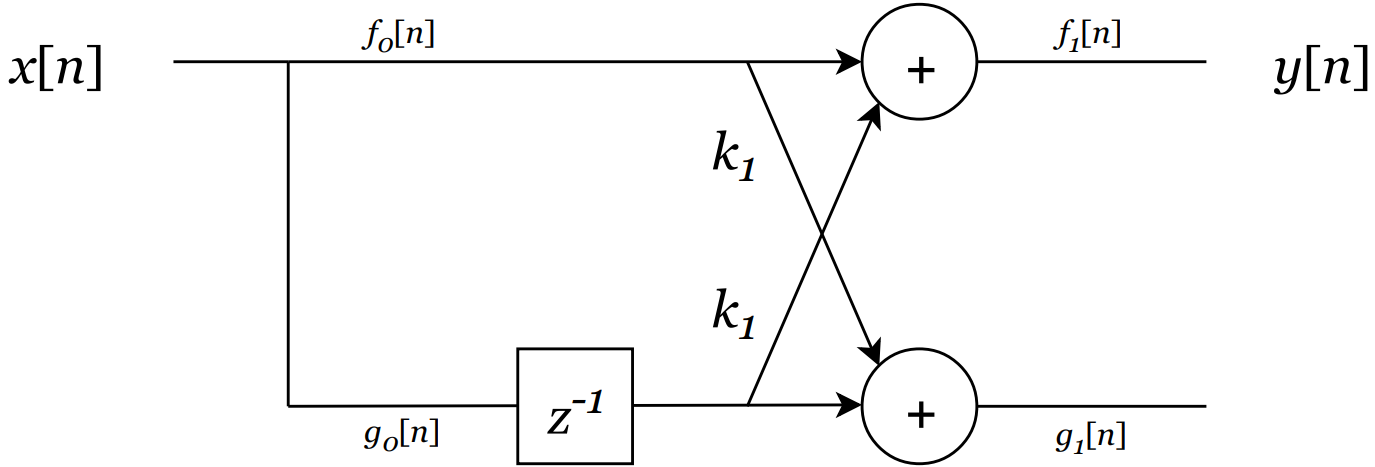

#### Two stage filter

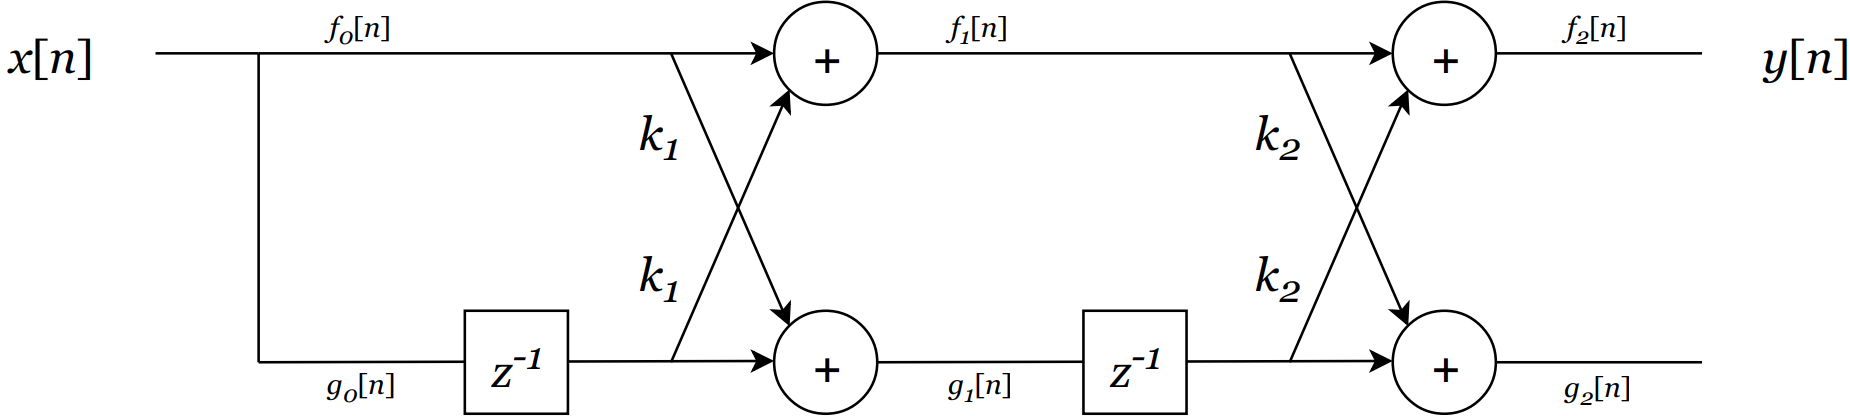

Compute the difference equations for the two FIR systems:


$$\begin{array}{l}
f_2 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack +k_2 g_1 \left\lbrack n-1\right\rbrack \\
g_2 \left\lbrack n\right\rbrack =k_2 \;f_1 \left\lbrack n\right\rbrack +g_1 \left\lbrack n-1\right\rbrack 
\end{array}$$



$$\begin{array}{l}
f_1 \left\lbrack n\right\rbrack =f_0 \left\lbrack n\right\rbrack +k_1 g_0 \left\lbrack n-1\right\rbrack \\
g_1 \left\lbrack n\right\rbrack =k_1 \;f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack 
\end{array}$$


If we substitute we get:


$$\begin{array}{l}
f_2 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack +k_2 g_1 \left\lbrack n-1\right\rbrack \\
f_2 \left\lbrack n\right\rbrack =f_0 \left\lbrack n\right\rbrack +k_1 g_0 \left\lbrack n-1\right\rbrack +k_2 \left(k_1 \;f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack \right)
\end{array}$$


Since $x\left\lbrack n\right\rbrack =f_0 \left\lbrack n\right\rbrack =g_0 \left\lbrack n\right\rbrack$ and $y\left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack$ then we can rewrite the difference equation for two stage all-zero lattice filter as:


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +k_1 \left(1+k_2 \right)x\left\lbrack n-1\right\rbrack +k_2 x\left\lbrack n-2\right\rbrack$$


Taking the z-transform, we have:


$$Y\left(z\right)=X\left(z\right)+k_1 \left(1+k_2 \right)z^{-1} X\left(z\right)+k_2 z^{-2} X\left(z\right)$$


We can compute the transfer function:


$$H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=1+k_1 \left(1+k_2 \right)z^{-1} +k_2 z^{-2}$$


#### Three stage filter

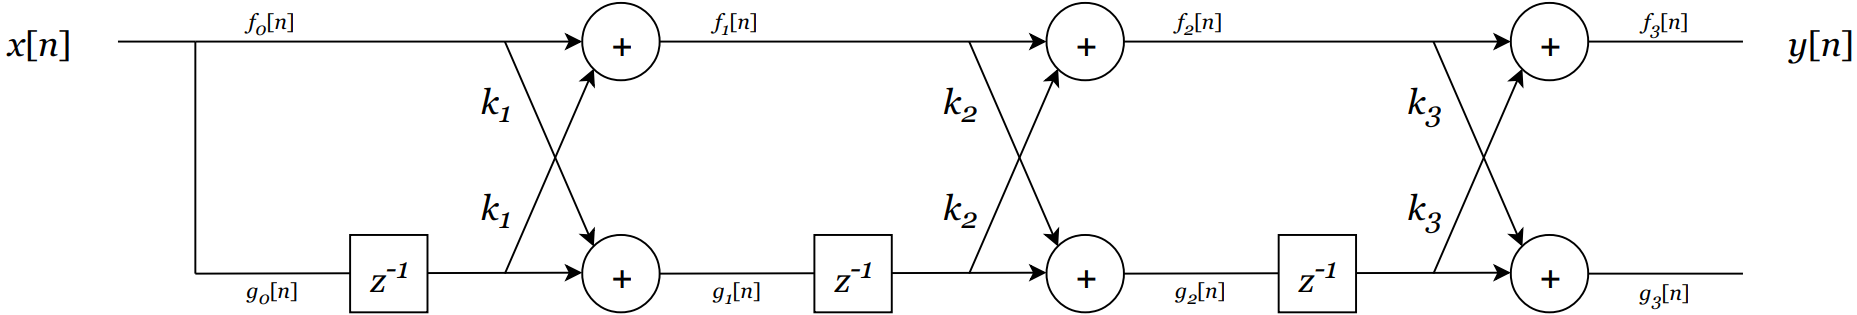

#### How to find reflection coefficients from the impulse response?

Suppose we want to determine the reflection coefficients $k_m ,m=1,2,\cdots ,M$ from the following an $M$th-order normalised FIR filter:


$$H\left(z\right)=\sum_{k=0}^M h\left\lbrack k\right\rbrack z^{-1}$$


First, we can define the filter coefficients as follows:

$a_k =\frac{h\left\lbrack k\right\rbrack }{h\left\lbrack 0\right\rbrack }$ where $k=0,1,\cdots ,M$

The recursive algorithm works as follows:

- Compute $A_M \left(z\right)=\frac{H\left(z\right)}{h\left\lbrack 0\right\rbrack }$

- Compute $k_M =a_M$ where $a_M$ is the last coefficients of $A_M \left(z\right)$. For example, if $A_M \left(z\right)=1+0\ldotp 06z^{-1} -0\ldotp 42z^{-2} +0\ldotp 5z^{-3}$ then $k_M =0\ldotp 5$

- Compute $B_M \left(z\right)$ by flipping the coefficients of $A_M \left(z\right)$

- Set $m=M$

- Compute $A_{m-1} \left(z\right)=\frac{1}{1-k_m^2 }\left\lbrack A_m \left(z\right)-k_m B_m \left(z\right)\right\rbrack$. Notice that this is where the algorithm fails because if $k_m =1\to k_m^2 =1$ then we will have division by zero.

- Compute $k_{m-1} =a_{m-1}$ where $a_{m-1}$ is the last coefficients of $A_{m-1} \left(z\right)$

- Compute $B_{m-1} \left(z\right)$ by flipping the coefficients of $A_{m-1} \left(z\right)$. Alternatively, compute $B_{m-1} \left(z\right)=z^{-m-1} A_{m-1} \left(\frac{1}{z}\right)$

- Set $m=m-1$

- Go to step 5 if $m\not= 0$

- We know that $A_0 \left(z\right)=B_0 \left(z\right)=1$

See page 513

### All-pole lattice structure

An ***all-pole*** lattice models an IIR system.

The figure below shows how an all-pole lattice structure looks like

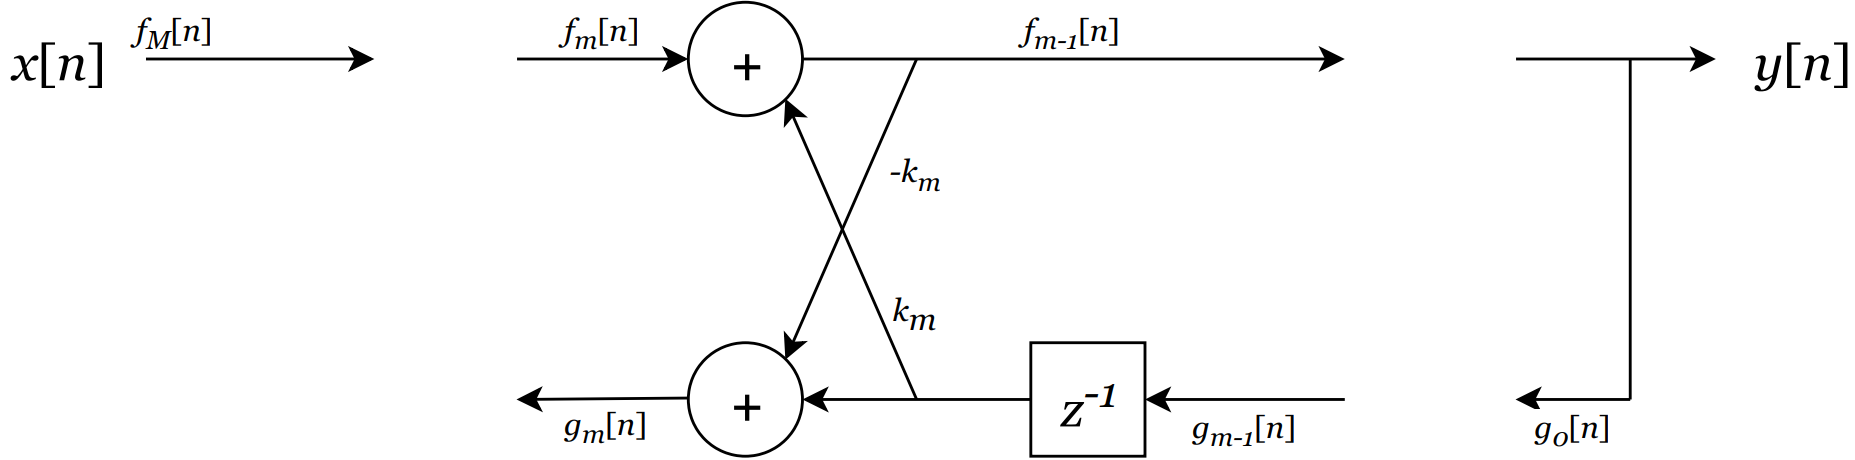


$$f_{m-1} \left\lbrack n\right\rbrack =f_m \left\lbrack n\right\rbrack -k_m g_{m-1} \left\lbrack n-1\right\rbrack$$



$$g_m \left\lbrack n\right\rbrack =k_m f_{m-1} \left\lbrack n\right\rbrack +g_{m-1} \left\lbrack n-1\right\rbrack$$


When $M=1$

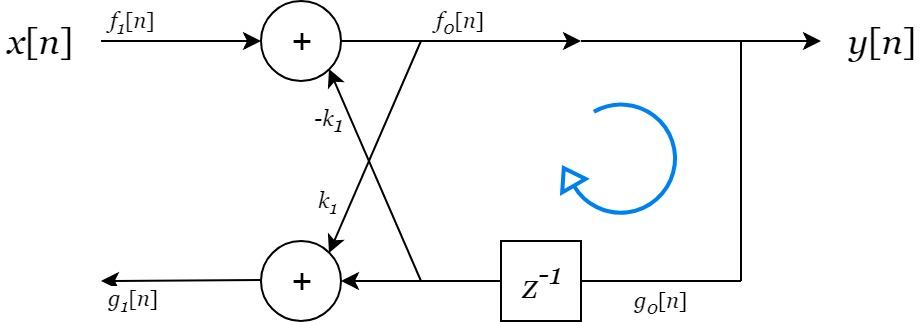

The difference equation for when $M=1$ is given as:


$$f_0 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack$$


Since $f_0 \left\lbrack n\right\rbrack =g_0 \left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack$ and $f_1 \left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack$ then we have the following difference equation


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -k_1 y\left\lbrack n-1\right\rbrack$$


This is the difference equation for a IIR filter!

If we take the z-transform, we get:


$$Y\left(z\right)=X\left(z\right)-k_1 Y\left(z\right)z^{-1}$$


We can compute the transfer function:


$$H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{1}{1+k_1 z^{-1} }=\frac{1}{A\left(z\right)}$$


Let us look at the other system $g_1 \left\lbrack n\right\rbrack$:


$$\begin{array}{l}
g_1 \left\lbrack n\right\rbrack =k_1 f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack \\
g_1 \left\lbrack n\right\rbrack =k_1 y\left\lbrack n\right\rbrack +y\left\lbrack n-1\right\rbrack 
\end{array}$$


It is clear that $g_1 \left\lbrack n\right\rbrack$ is a FIR filter of the output.

When $M=2$

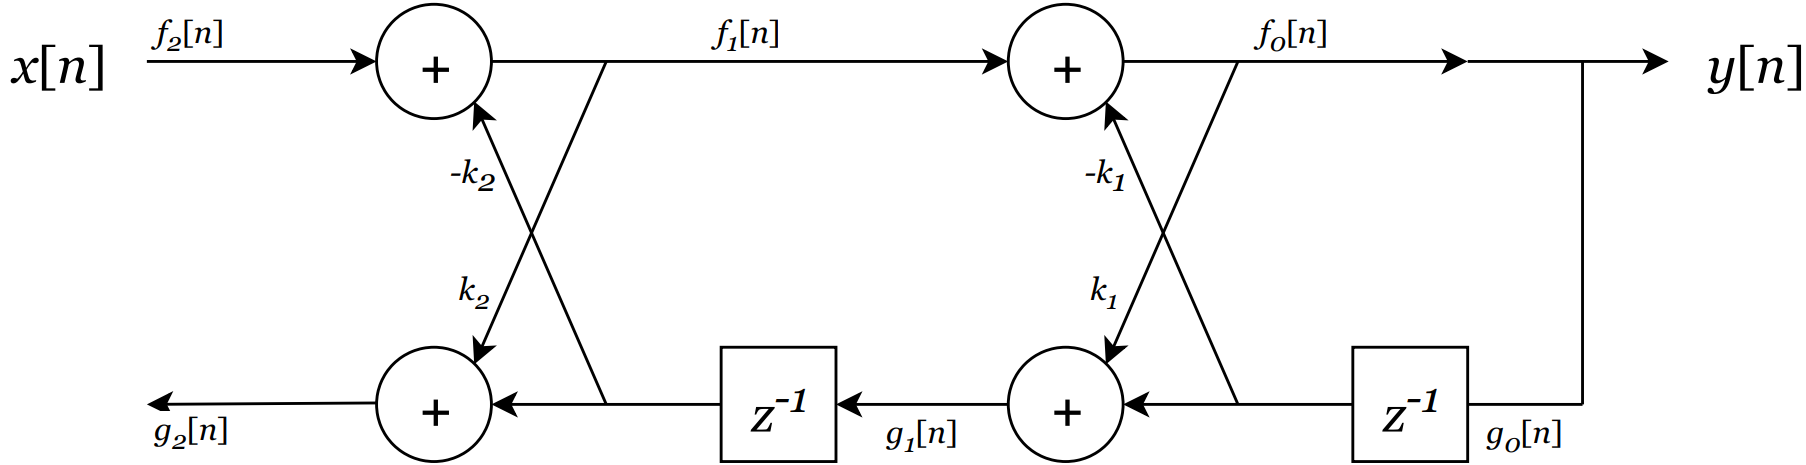

We compute the difference equations from the output:


$$f_0 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack$$



$$g_1 \left\lbrack n\right\rbrack =k_1 f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack$$


The next stage:


$$f_1 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 g_1 \left\lbrack n-1\right\rbrack$$



$$g_2 \left\lbrack n\right\rbrack =k_2 f_1 \left\lbrack n\right\rbrack +g_1 \left\lbrack n-1\right\rbrack$$


We can substitute:


$$\begin{array}{l}
f_0 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 g_1 \left\lbrack n-1\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack \\
f_0 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 \left(k_1 f_0 \left\lbrack n-1\right\rbrack +g_0 \left\lbrack n-2\right\rbrack \right)-k_1 g_0 \left\lbrack n-1\right\rbrack 
\end{array}$$


Since $f_0 \left\lbrack n\right\rbrack =g_0 \left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack$ and $f_2 \left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack$ then we have:


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -k_2 \left(k_1 y\left\lbrack n-1\right\rbrack +y\left\lbrack n-2\right\rbrack \right)-k_1 y\left\lbrack n-1\right\rbrack \\
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -k_1 \left(1+k_2 \right)y\left\lbrack n-1\right\rbrack -k_2 y\left\lbrack n-2\right\rbrack 
\end{array}$$


If we take the z-transform, we get:


$$Y\left(z\right)=X\left(z\right)-k_1 \left(1+k_2 \right)Y\left(z\right)z^{-1} -k_2 Y\left(z\right)z^{-2}$$


The transfer function becomes:


$$\frac{Y\left(z\right)}{X\left(z\right)}=\frac{1}{1+k_1 \left(1+k_2 \right)z^{-1} +k_2 z^{-2} }$$


### What are the advantages of lattice structures?

When is an all-pole filter stable?

The all-zero and all-pole lattice structures require twice the number of multiplications per output sample as the direct forms. However, they have two unique advantages compared to direct form structures. 

The first advantage follows from the following theorem:  

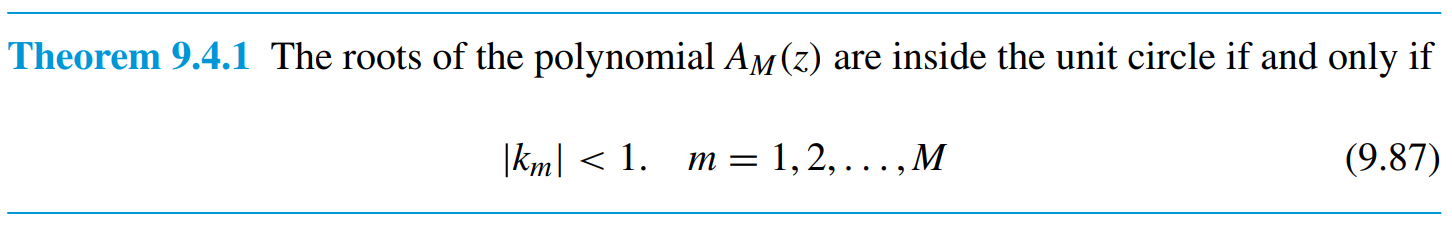

**Advantage 1:** If the lattice parameters satisfy Eq. (9.87) then the all-zero lattice filter is **minimum-phase** and the all-pole filter is **stable**.

**Advantage 2:** Lattice structures are insensitive to quantization of the *k*-parameters.

## [✔] ADSI Problem 2.1: Implementation of All-zero lattice filters

Work you way through the MATLAB code in Figure 9.26 and make sure you understand what is going on.  

## [✔] ADSI Problem 2.2: Find impulse response of an all-zero lattice filter

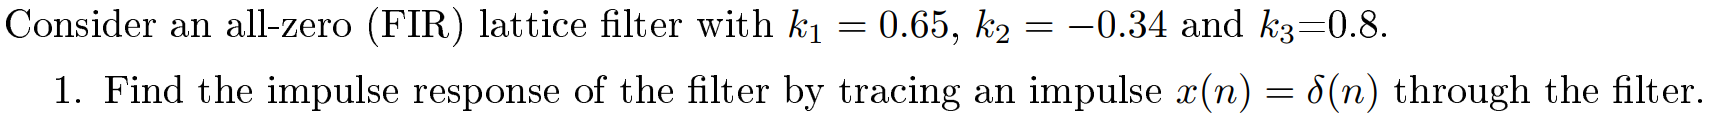

Since the lattice filter has three reflection coefficients, it is a 3-stage all-zero lattice filter.

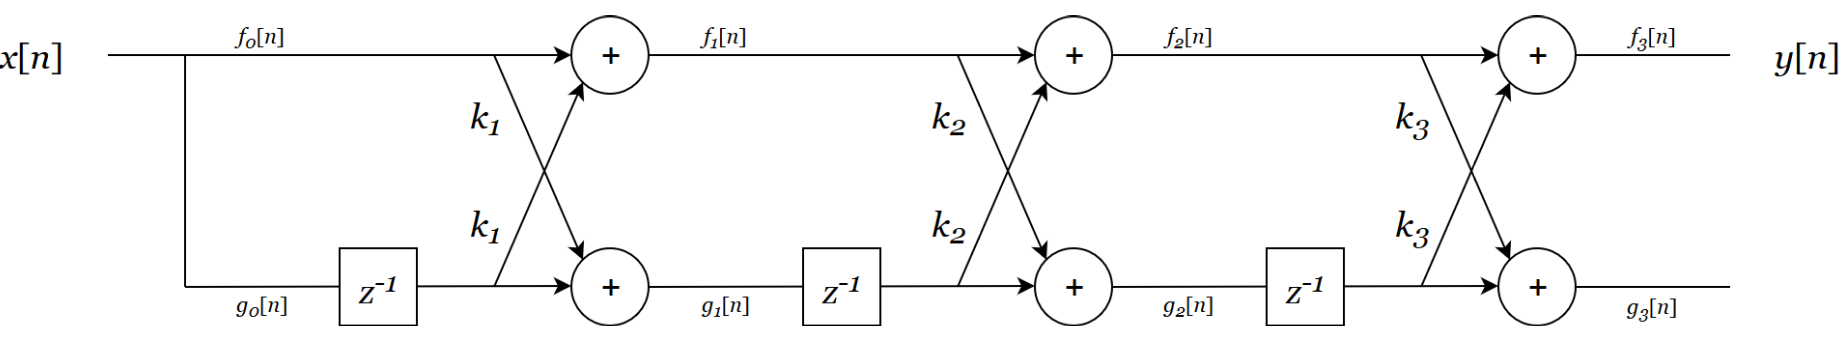

Here are the formulas needed to trace through the filter.

        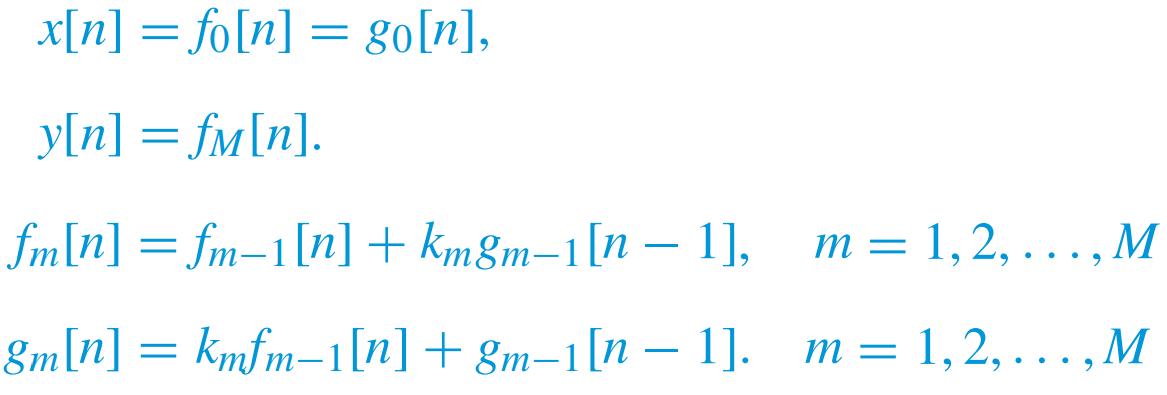

The input is $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack =\left\lbrack 1,0,0,0\right\rbrack$

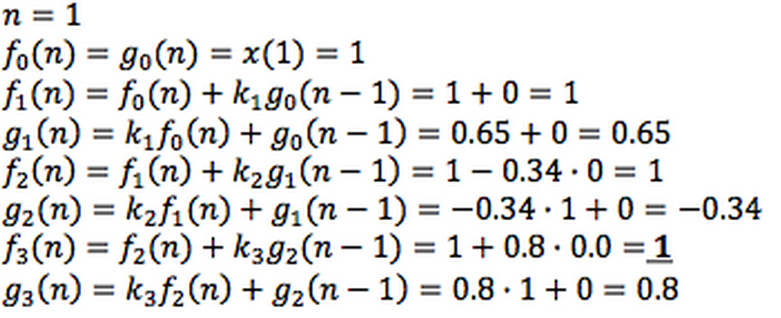

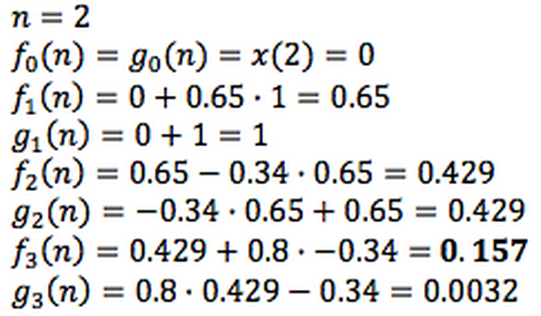

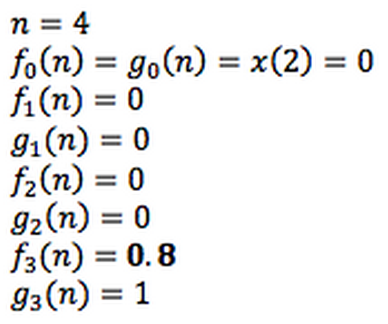

We can also use the MATLAB function **azlatfilt** given in Figure 9.26 in the book.

k = [0.65, -0.34, 0.8];
x = [1, 0, 0, 0];
G = 1;
y = azlatfilt(k, x, G)

y =     1.0000    0.1570    0.0032    0.8000


The impulse response of the given filter is:


$$h\left\lbrack n\right\rbrack =\left\lbrack 1,0\ldotp 157,0\ldotp 0032,0\ldotp 8\right\rbrack$$


## [✔] ADSI Problem 2.3: Find the reflection coefficients for an all-zero lattice filter

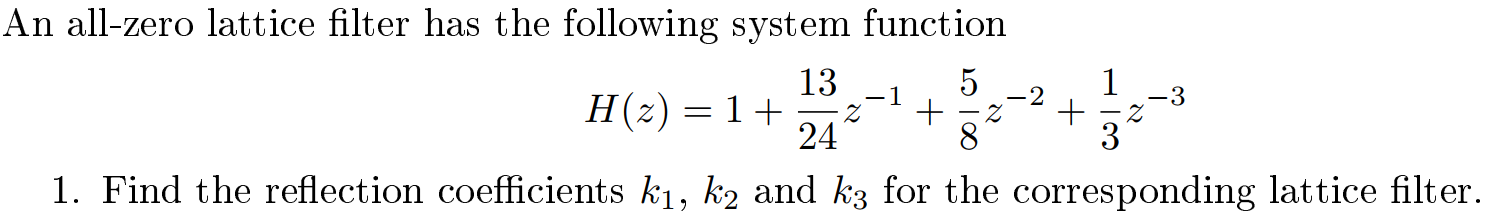

Can be computed using MATLAB function ***tf2latc*** to convert transfer function filter parameters to lattice filter for:

b = [1, 13/24, 5/8, 1/3];
a = 1;
k = tf2latc(b, a)

k =     0.2500
    0.5000
    0.3333


We can also try the algorithm (Figure 9.24) from the book

k = fir2lat(b)'

k =     0.2500
    0.5000
    0.3333


We can also do it by hand using the recursive algorithm:

The recursive algorithm works as follows:

- Compute $A_M \left(z\right)=\frac{H\left(z\right)}{h\left\lbrack 0\right\rbrack }$

- Compute $k_M =a_M$ where $a_M$ is the last coefficients of $A_M \left(z\right)$. For example, if $A_M \left(z\right)=1+0\ldotp 06z^{-1} -0\ldotp 42z^{-2} +0\ldotp 5z^{-3}$ then $k_M =0\ldotp 5$

- Compute $B_M \left(z\right)$ by flipping the coefficients of $A_M \left(z\right)$

- Set $m=M$

- Compute $A_{m-1} \left(z\right)=\frac{1}{1-k_m^2 }\left\lbrack A_m \left(z\right)-k_m B_m \left(z\right)\right\rbrack$. Notice that this is where the algorithm fails because if $k_m =1\to k_m^2 =1$ then we will have division by zero.

- Compute $k_{m-1} =a_{m-1}$ where $a_{m-1}$ is the last coefficients of $A_{m-1} \left(z\right)$

- Compute $B_{m-1} \left(z\right)$ by flipping the coefficients of $A_{m-1} \left(z\right)$. Alternatively, compute $B_{m-1} \left(z\right)=z^{-m-1} A_{m-1} \left(\frac{1}{z}\right)$

- Set $m=m-1$

- Go to step 5 if $m\not= 0$

- We know that $A_0 \left(z\right)=B_0 \left(z\right)=1$

In this problem, we have a 3-stage all-zero lattice filter:

We are given its transfer function:


$$H\left(z\right)=1+\frac{13}{24}z^{-1} +\frac{5}{8}z^{-2} +\frac{1}{3}z^{-3}$$


Since this is a FIR system of the form:


$$H\left(z\right)=\sum_{k=0}^M h\left\lbrack k\right\rbrack z^{-1}$$


We know that $M=3$, $h\left\lbrack k\right\rbrack =\left\lbrack 1,\frac{13}{24},\frac{5}{8},\frac{1}{8}\right\rbrack$ and $h\left\lbrack 0\right\rbrack =1$.

**Step 1: Compute **$A_3 \left(z\right)$

    
$$A_M \left(z\right)=A_3 \left(z\right)=\frac{H\left(z\right)}{h\left\lbrack 0\right\rbrack }=\frac{H\left(z\right)}{1}=1+\frac{13}{24}z^{-1} +\frac{5}{8}z^{-2} +\frac{1}{3}z^{-3}$$


**Step 2: Compute **$k_3$

The last coefficients of $A_3 \left(z\right)$ is $\frac{1}{3}$ so $k_3 =\frac{1}{3}$

**Step 3: Compute **$B_3 \left(z\right)$

Once we have $A_M \left(z\right)$, we can compute $B_M \left(z\right)$ by simply flipping the coefficients of $A_M \left(z\right)$.

    
$$B_M \left(z\right)=B_3 \left(z\right)=\frac{1}{3}+\frac{5}{8}z^{-1} +\frac{13}{24}z^2 +z^{-3}$$


**Step 4: Set **$m=M$

    
$$m=3$$


**Step 5: Compute **$A_2 \left(z\right)$

Using the formula $A_{m-1} \left(z\right)=\frac{1}{1-k_m^2 }\left\lbrack A_m \left(z\right)-k_m B_m \left(z\right)\right\rbrack$ we can compute $A_2 \left(z\right)$

    
$$A_2 \left(z\right)=\frac{1}{1-k_3^2 }\left\lbrack A_3 \left(z\right)-k_3 B_3 \left(z\right)\right\rbrack$$


    
$$A_2 \left(z\right)=\frac{1}{1-{\left(\frac{1}{3}\right)}^2 }\left\lbrack \left(1+\frac{13}{24}z^{-1} +\frac{5}{8}z^{-2} +\frac{1}{3}z^{-3} \right)-\frac{1}{3}\left(\frac{1}{3}+\frac{5}{8}z^{-1} +\frac{13}{24}z^2 +z^{-3} \right)\right\rbrack$$


    
$$A_2 \left(z\right)=\frac{9}{8}\left\lbrack 1-\frac{1}{3}\cdot \frac{1}{3}+\left(\frac{13}{24}-\frac{1}{3}\cdot \frac{5}{8}\right)z^{-1} +\left(\frac{5}{8}-\frac{1}{3}\cdot \frac{13}{24}\right)z^{-2} +\left(\frac{1}{3}-\frac{1}{3}\right)z^{-3} \right\rbrack$$


    
$$A_2 \left(z\right)=\frac{9}{8}\left\lbrack \frac{8}{9}+\frac{1}{3}z^{-1} +\frac{4}{9}z^{-2} +0z^{-3} \right\rbrack$$


    
$$A_2 \left(z\right)=1+\frac{3}{8}z^{-1} +\frac{1}{2}z^{-2}$$


**Step 6: Compute **$k_2$

We can read of the last coefficient of $A_2 \left(z\right)$ which is $k_2 =\frac{1}{2}$

**Step 7: Compute **$B_2 \left(z\right)$

Once we have $A_2 \left(z\right)$, we can compute $B_2 \left(z\right)$ by simply flipping the coefficients of $A_2 \left(z\right)$.

    
$$B_2 \left(z\right)=\frac{1}{2}+\frac{3}{8}z^{-1} +z^{-2}$$


**Step 8: Set **$m=2$

**Step 9:** Go to step 5

**Step 5: Compute **$A_1 \left(z\right)$

We can compute $A_1 \left(z\right)$ as follows

    
$$A_1 \left(z\right)=\frac{1}{1-k_2^2 }\left\lbrack A_2 \left(z\right)-k_2 B_2 \left(z\right)\right\rbrack$$


    
$$A_1 \left(z\right)=\frac{1}{1-{\left(\frac{1}{2}\right)}^2 }\left\lbrack \left(1+\frac{3}{8}z^{-1} +\frac{1}{2}z^{-2} \right)-\frac{1}{2}\left(\frac{1}{2}+\frac{3}{8}z^{-1} +z^{-2} \right)\right\rbrack$$


    
$$A_1 \left(z\right)=\frac{4}{3}\left\lbrack 1-\frac{1}{2}\cdot \frac{1}{2}+\left(\frac{3}{8}-\frac{1}{2}\cdot \frac{3}{8}\right)z^{-1} +\left(\frac{1}{2}-\frac{1}{2}\right)z^{-2} \right\rbrack$$


    
$$A_1 \left(z\right)=\frac{4}{3}\left\lbrack \frac{3}{4}+\frac{3}{16}z^{-1} +0z^{-2} \right\rbrack$$


    
$$A_1 \left(z\right)=1+\frac{1}{4}z^{-1}$$


**Step 6: Compute **$k_1$

We can read of the last coefficient of $A_1 \left(z\right)$ which is $k_1 =\frac{1}{4}$

We are done! The result is $k_1 =\frac{1}{4}$, $k_2 =\frac{1}{2}$ and $k_3 =\frac{1}{3}$

The reflection coefficients are $k_1 =\frac{1}{4},k_2 =\frac{1}{2},k_3 =\frac{1}{3}$

## [✔] ADSI Problem 2.5: All-zero lattice filter, find coefficients from system function (division by zero problem) 

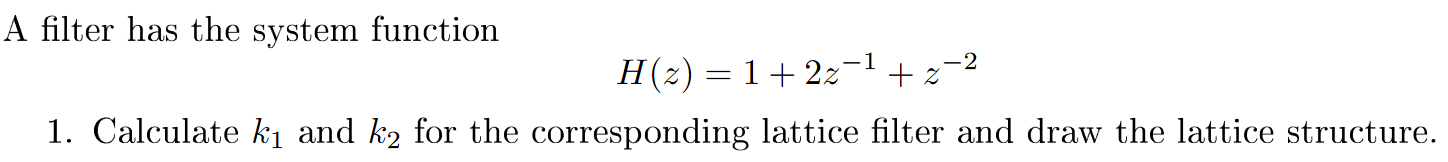

clear variables;

We cannot use a recursive algorithm if one of the reflection coefficients is equal to 1. In this problem, $k_2 =1$ so if we attempt to compute $A_1 \left(z\right)$, it will lead to division by zero:

        
$$A_1 \left(z\right)=\frac{1}{1-k_2^2 }\left\lbrack A_2 \left(z\right)-k_2 B_2 \left(z\right)\right\rbrack =\frac{1}{1-1}\left\lbrack A_2 \left(z\right)-k_2 B_2 \left(z\right)\right\rbrack$$


We can try out it out in MATLAB function:

b = [1, 2, 1];
a = 1;
% tf2latc(b) % This fails because one coeff. is 1

Instead we can use a cascade of two single-stage filters.

First, we factorise the original FIR filter to two cascade filters. This can be done by finding the roots and using the formula:

        $H\left(z\right)=\left(1-r_1 z^{-1} \right)\left(1-r_2 z^{-1} \right)\cdots \left(1-r_M z^{-1} \right)$ where $r_i$ are the roots of the transfer function.

Find the roots:

roots(b)

ans =     -1
    -1


Factorise the original FIR filter into two cascading filters:

        
$$H\left(z\right)=\left(1-\left(-1\right)z^{-1} \right)\left(1-\left(-1\right)z^{-1} \right)=\left(1+z^{-1} \right)\left(1+z^{-1} \right)$$


Recall that that a single stage all-zero filter has following difference equation:

        
$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +k_1 x\left\lbrack n-1\right\rbrack$$


Taking the z-transform we get:

        
$$Y_{\mathrm{az}} \left(z\right)=X_{\mathrm{az}} \left(z\right)+k_1 X_{\mathrm{az}} \left(z\right)z^{-1}$$


The system function of a single stage all-zero lattice filter is therefore:

        
$$H_{\mathrm{az}} \left(z\right)=\frac{Y_{\mathrm{az}} \left(z\right)}{X_{\mathrm{az}} \left(z\right)}=1+k_1 z^{-1}$$


It turns out that we can cascade two single stage all-zero lattice filters the same way as we cascade FIR filters.

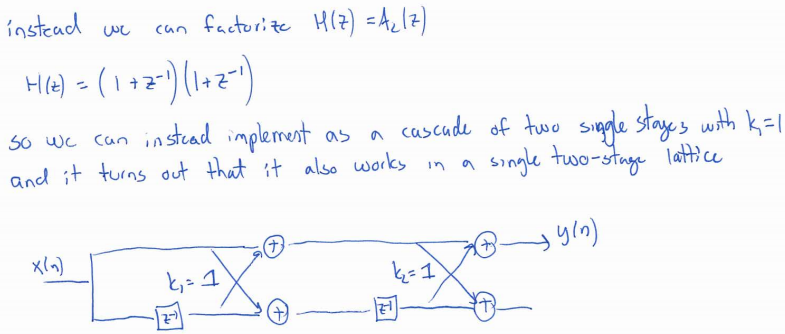

So in our case, we have $k_1 =1$ and $k_2 =1$.

Let us check if we can get the impulse response of the original filter.

k = [1, 1];
lat2fir(k, 1)

ans =      1     2     1


latc2tf(k) % Same as lat2fir

ans =      1     2     1


Success! 

## [✔] ADSI Problem 2.7: Find system function an all-pole filter from reflection coefficients

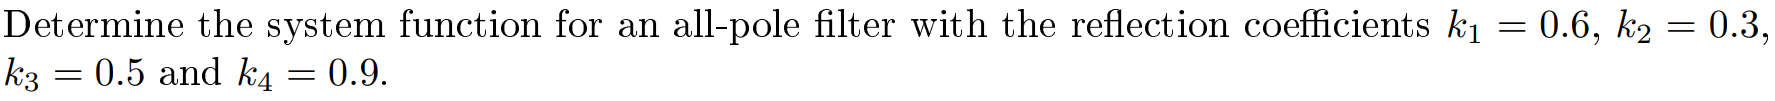

clear variables;

Use MATLAB to compute the transfer function:

k = [0.6, 0.3, 0.5, 0.9];
[num, dem] = latc2tf(k, 'allpole')

num =      1     0     0     0     0


dem =     1.0000    1.3800    1.3110    1.3370    0.9000


The system function is:

        
$$H\left(z\right)=\frac{1}{1+1\ldotp 38z^{-1} +1\ldotp 311z^{-2} +1\ldotp 337z^{-3} +0\ldotp 9z^{-4} }$$


Alternatively, do it by hand using following two formulas:

    
$$f_{m-1} \left\lbrack n\right\rbrack =f_m \left\lbrack n\right\rbrack -k_m g_{m-1} \left\lbrack n-1\right\rbrack$$


    
$$g_m \left\lbrack n\right\rbrack =k_m f_{m-1} \left\lbrack n\right\rbrack +g_{m-1} \left\lbrack n-1\right\rbrack$$


We start computing the difference equations of the last section:

    
$$f_0 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack$$


    
$$g_1 \left\lbrack n\right\rbrack =k_1 f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack$$


Then we compute the next stage:

    
$$f_1 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 g_1 \left\lbrack n-1\right\rbrack$$


    
$$g_2 \left\lbrack n\right\rbrack =k_2 f_1 \left\lbrack n\right\rbrack +g_1 \left\lbrack n-1\right\rbrack$$


Next, we can substitute $f_1 \left\lbrack n\right\rbrack$ into the expression $f_0 \left\lbrack n\right\rbrack$:

    
$$\begin{array}{l}
f_0 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 g_1 \left\lbrack n-1\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack \\
f_0 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 \left(k_1 f_0 \left\lbrack n-1\right\rbrack +g_0 \left\lbrack n-2\right\rbrack \right)-k_1 g_0 \left\lbrack n-1\right\rbrack 
\end{array}$$


And so on. 

Finally, we will get a large expression in which we replace:

- $g_0 \left\lbrack n\right\rbrack$ and $f_0 \left\lbrack n\right\rbrack$ with $y\left\lbrack n\right\rbrack$

- $f_4 \left\lbrack n\right\rbrack$ with $x\left\lbrack n\right\rbrack$

## [✔] ADSI Problem 2.10: Linear prediction and lattice filters  

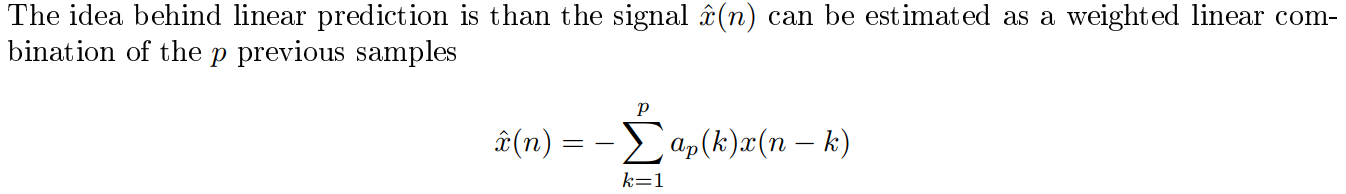

clear variables;

### 1) Compute autocorrelation from a signal

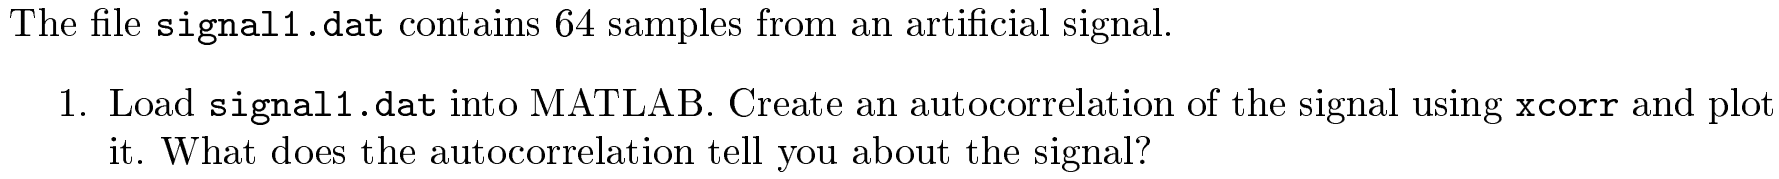

Let us first plot the signal.

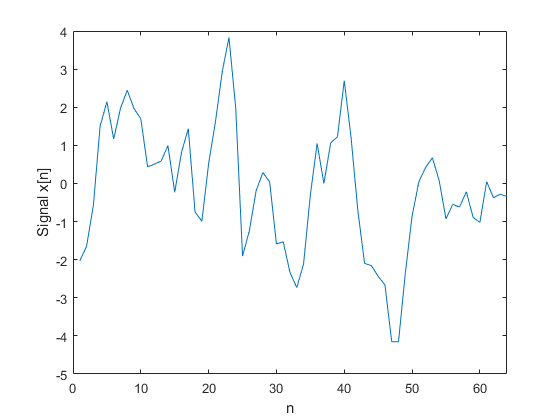

x = importdata('signal1.dat');
plot(x);
xlabel('n');
ylabel('Signal x[n]');
xlim([0, numel(x)]);

Autocorrelation is the cross-correlation between a signal $x\left\lbrack n\right\rbrack$ with the same signal shifted by some amount $x\left\lbrack n-k\right\rbrack$. So if we start with $k=1$, we compute the correlation between $x\left\lbrack n\right\rbrack$ and $x\left\lbrack n-1\right\rbrack$. For $k=2$, we compute the correlation between $x\left\lbrack n\right\rbrack$ and $x\left\lbrack n-2\right\rbrack$ etc.

Autocorrelation is symmetrical around zero.

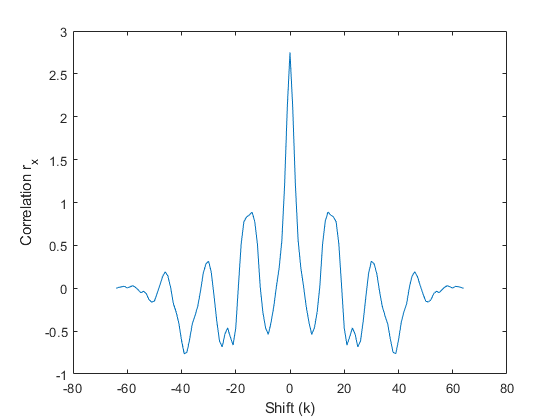

[r,lags] = xcorr(x,64,'biased');
plot(lags,r);
xlabel('Lag (l)');
ylabel('r_x(l)');

From the plot, we see that when the signal is shifted e.g. by 4, the correlation is low. 

r(4)

ans = 0.0223

r(50)

ans = 0.8533

This means that the original signal $x\left\lbrack n\right\rbrack$ and the shifted signal $x\left\lbrack n-4\right\rbrack$ are not very similar. The correlation is higher when the signal is shifted by 50:

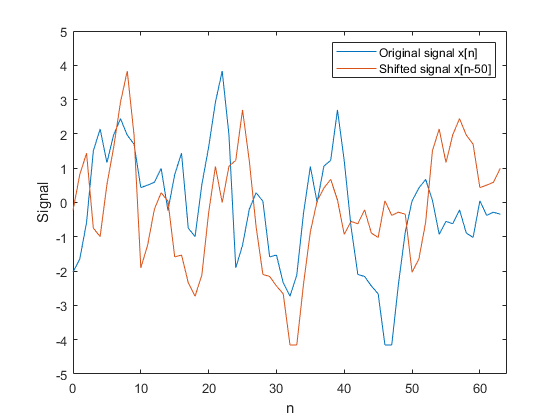

n = linspace(0, 63, 64)';
x_shifted_50 = circshift(x, 50);
plot(n, x, n, x_shifted_50);
legend('Original signal x[n]','Shifted signal x[n-50]')
xlabel('n');
ylabel('Signal');
xlim([0, numel(x)]);
ylim([-5, 5])

Shifting the signal by 64 yields the highest correlation. This makes sense because if we shift a signal of length 64 by 64 then we get the original signal $x\left\lbrack n\right\rbrack =x\left\lbrack n-64\right\rbrack$.

r(64+1)

ans = 2.7507

### 2) Compute the coefficients for the optimum 2nd-order linear predictor

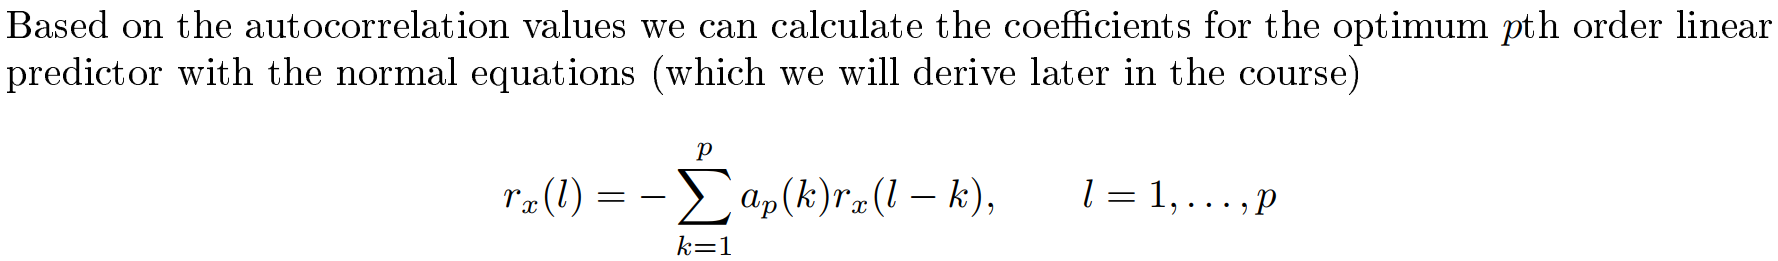

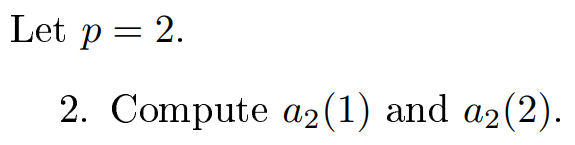

When $p=2$ then we get following two equations:


$$\begin{array}{l}
r_x \left(1\right)=-a_2 \left(1\right)r_x \left(0\right)-a_2 \left(2\right)r_x \left(-1\right)\\
r_x \left(2\right)=-a_2 \left(1\right)r_x \left(1\right)-a_2 \left(2\right)r_x \left(0\right)
\end{array}$$


In exercise 1) we computed the correlation values $r_x$. So we know the values for $r_x \left(-1\right)$, $r_x \left(0\right)$, $r_x \left(1\right)$ and $r_x \left(2\right)$. This means that we have to solve two equations with two unknowns. 

Let us rewrite it:


$$\begin{array}{l}
r_x \left(1\right)+a_2 \left(1\right)r_x \left(0\right)+a_2 \left(2\right)r_x \left(-1\right)=0\\
r_x \left(2\right)+a_2 \left(1\right)r_x \left(1\right)+a_2 \left(2\right)r_x \left(0\right)=0
\end{array}$$


Solve it in MATLAB:

syms a2_1 a2_2

% The autocorrelation is centered around zero
% Find the index where n=0
centerIx = find(lags==0);

% Retrive the values r(-1), r(0), r(1) and r(2) in order
rx_m1 = r(centerIx - 1);
rx_0 = r(centerIx + 0);
rx_1 = r(centerIx + 1);
rx_2 = r(centerIx + 2);

eq1 = rx_1 + a2_1*rx_0 + a2_2*rx_m1;
eq2 = rx_2 + a2_1*rx_1 + a2_2*rx_0;

sol = solve([eq1, eq2], [a2_1, a2_2]);

a1 = sol.a2_1;
a2 = sol.a2_2;
% Print the value of a2(1)
vpa(sol.a2_1)

$$ans = -1.0554484225972357733576990520746$$

% Print the value of a2(2)
vpa(sol.a2_2)

$$ans = 0.37530590522885965170506927041028$$

The coefficents of the predictor are $a_2 \left(1\right)\approx -1\ldotp 0554$ and $a_2 \left(2\right)\approx \;0\ldotp 3753$

### 3) Compare the linear predictor with a two-stage all-zero lattice filter

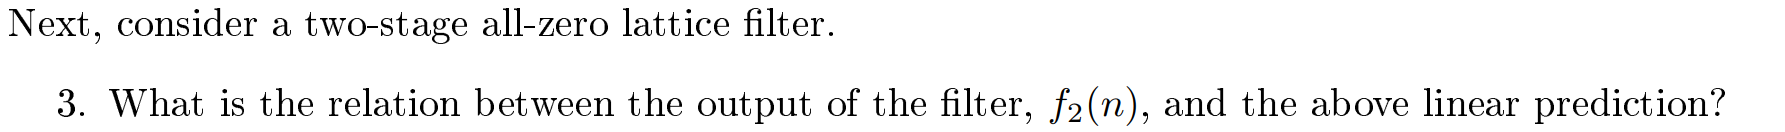

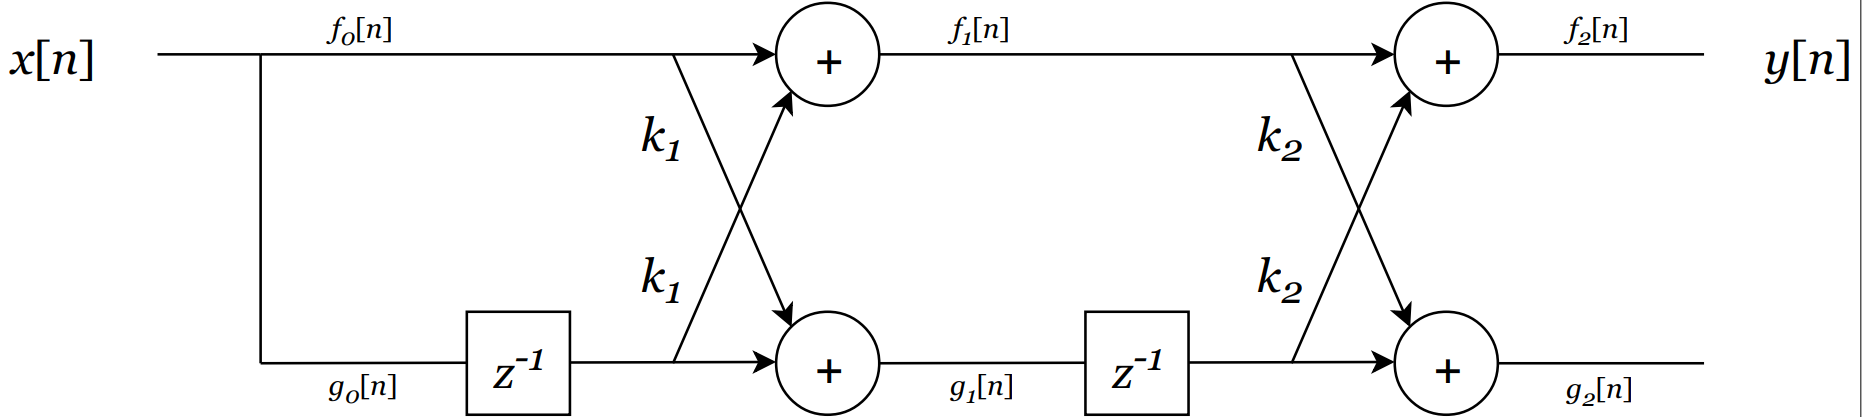

We know that the output of a two-stage all-zero lattice filter is:

        
$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +k_1 \left(1+k_2 \right)x\left\lbrack n-1\right\rbrack +k_2 x\left\lbrack n-2\right\rbrack$$


The p'th order linear predictor has the following form:

        
$$\hat{x} \left\lbrack n\right\rbrack =\sum_{k=1}^p a_k \cdot \left\lbrack n-k\right\rbrack$$


So the second-order linear predictor has the form:

        
$$\hat{x} \left\lbrack n\right\rbrack =a_1 x\left\lbrack n-1\right\rbrack +a_2 x\left\lbrack n-2\right\rbrack$$


Notice that 2nd order linear predictor looks very much like the difference equation for the two-stage all-zero lattice filter.

There is a one-to-one correspondance between their coefficients where $a_1 =k_1 \left(1+k_2 \right)$ and $a_2 =k_2$.

### 4) Compute reflection coefficients from the linear predictor

From 3) we found that $a_1 =k_1 \left(1+k_2 \right)$ and $a_2 =k_2$ so:


$$\begin{array}{l}
k_2 =a_2 \\
k_1 =\frac{a_1 }{1+a_2 }
\end{array}$$


In 2) we found that values for $a_1$ and $a_2$. We will use these to compute $k_1$ and $k_2$:

k1 = a2/(1+a2);
k2 = a2;
vpa(k1)

$$ans = 0.27288903785111455734521239333629$$

vpa(k2)

$$ans = 0.37530590522885965170506927041028$$

So we have $k_1 \approx 0\ldotp 272889$ and $k_2 \approx 0\ldotp 3753$

### 5) Compute prediction error

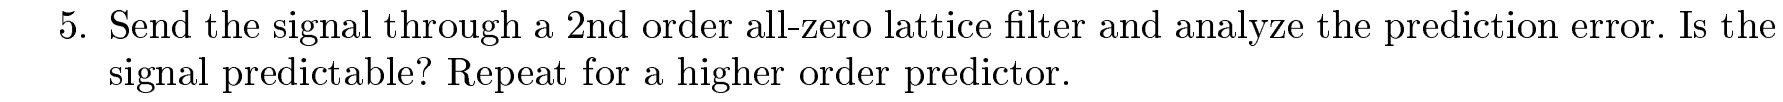

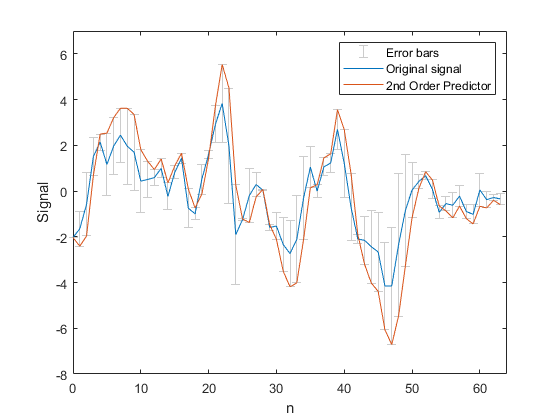

figure;

% Compute x_hat and err
n = linspace(0, 63, 64);
x = importdata('signal1.dat');
x_hat = azlatfilt([k1, k2], x, 1);
err = x_hat - x;

% Plot
errorbar(n, x, err, 'LineStyle','none', 'Color', [0.8, 0.8, 0.8]);

hold on;
plot(n, x);
plot(n, x_hat);
hold off;

xlabel('n');
ylabel('Signal');
xlim([0, numel(x)]);
ylim([-8, 7])
legend('Error bars', 'Original signal', '2nd Order Predictor');

## Exam 2016 Problem 3: All-pole Lattice Filter

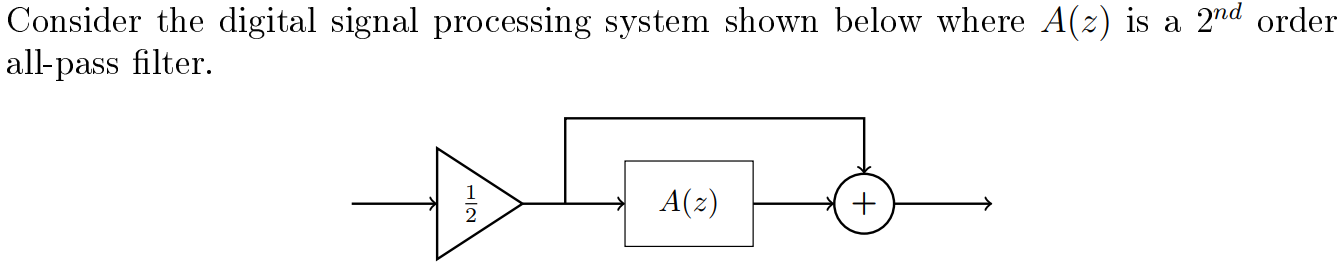

### 1) Explain why a system is a digital notch filter

Since *A*(*z*) is an all-pass filter, all frequencies pass un-attenuated but a frequency dependent phase shift is imposed on the signal.

Assume an input signal $x\left(n\right)=\alpha \;\mathrm{cos}\left(\omega n\right)$. If the two signals at the summing point are in phase the output is just equal to the input. For any other phase shift, the two signals will partly cancel out with the degree of cancellation depending on the phase shift.

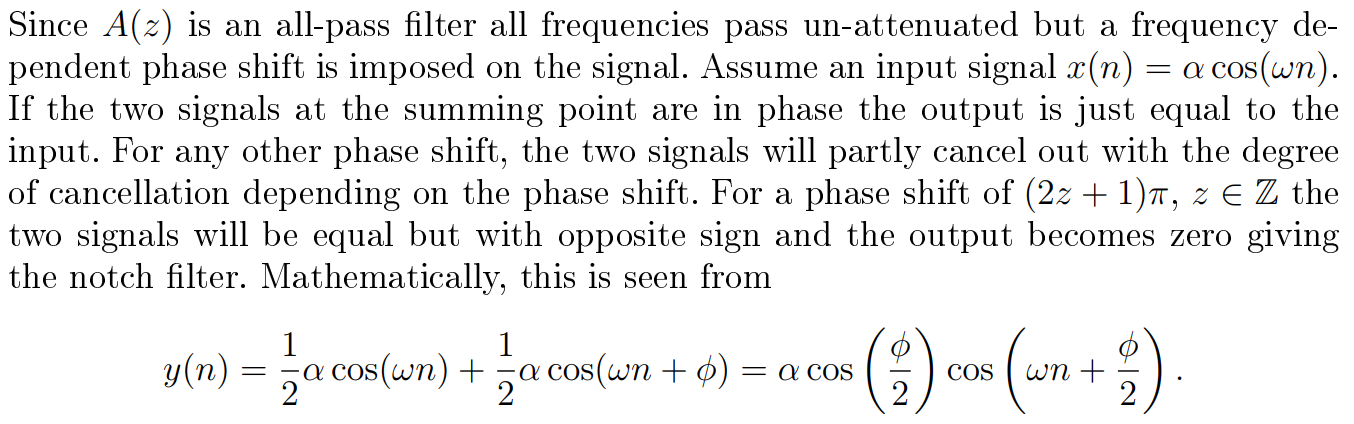

### 2) Find reflection coefficients for the all-pole lattice filter

The all-pass filter can be implemented as an all-pole lattice filter. Assume that

        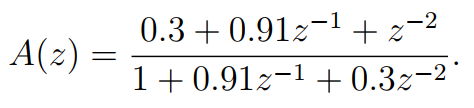

The recursive algorithm works as follows:

- Compute $A_M \left(z\right)=\frac{H\left(z\right)}{h\left\lbrack 0\right\rbrack }$

- Compute $k_M =a_M$ where $a_M$ is the last coefficients of $A_M \left(z\right)$. 

- Compute $B_M \left(z\right)$ by flipping the coefficients of $A_M \left(z\right)$

- Set $m=M$

- Compute $A_{m-1} \left(z\right)=\frac{1}{1-k_m^2 }\left\lbrack A_m \left(z\right)-k_m B_m \left(z\right)\right\rbrack$.

- Compute $k_{m-1} =a_{m-1}$ where $a_{m-1}$ is the last coefficients of $A_{m-1} \left(z\right)$

- Compute $B_{m-1} \left(z\right)$ by flipping the coefficients of $A_{m-1} \left(z\right)$. Alternatively, compute $B_{m-1} \left(z\right)=z^{-m-1} A_{m-1} \left(\frac{1}{z}\right)$

- Set $m=m-1$

- Go to step 5 if $m\not= 0$

- We know that $A_0 \left(z\right)=B_0 \left(z\right)=1$

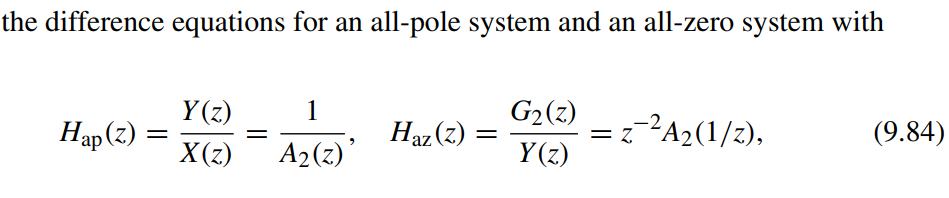

where 

        

From the system function of the all-pass filter, we know that:

        $A_2 \left(z\right)=1+0\ldotp 91z^{-1} +0\ldotp 3z^{-2}$  and $k_2 =a_2^{\left(2\right)\;} =0\ldotp 3$

We compute $B_2$:

        
$$B_2 =0\ldotp 3+0\ldotp 91z^{-1} +z^{-2}$$


We compute $A_1$:

        
$$A_1 \left(z\right)=\frac{1}{1-k_2^2 }\left\lbrack A_2 \left(z\right)-k_2 B_2 \left(z\right)\right\rbrack$$


        
$$A_1 \left(z\right)=\frac{1}{1-0\ldotp 3^2 }\left\lbrack \left(1+0\ldotp 91z^{-1} +0\ldotp 3z^{-2} \right)-0\ldotp 3\left(0\ldotp 3+0\ldotp 91z^{-1} +z^{-2} \right)\right\rbrack$$


        
$$A_1 \left(z\right)=\frac{1}{1-0\ldotp 3^2 }\left\lbrack 1+0\ldotp 91z^{-1} +0\ldotp 3z^{-2} -0\ldotp 09-0\ldotp 2730z^{-1} -0\ldotp 3z^{-2} \right\rbrack$$


        
$$A_1 \left(z\right)=1\ldotp 0989\left\lbrack 0\ldotp 91+0\ldotp 6370z^{-1} \right\rbrack$$


        
$$A_1 \left(z\right)=1+0\ldotp 7z^{-1}$$


with $k_1 =a_1^{\left(1\right)} =0\ldotp 7$

### 3) Determine the group delay in the digital notch filter

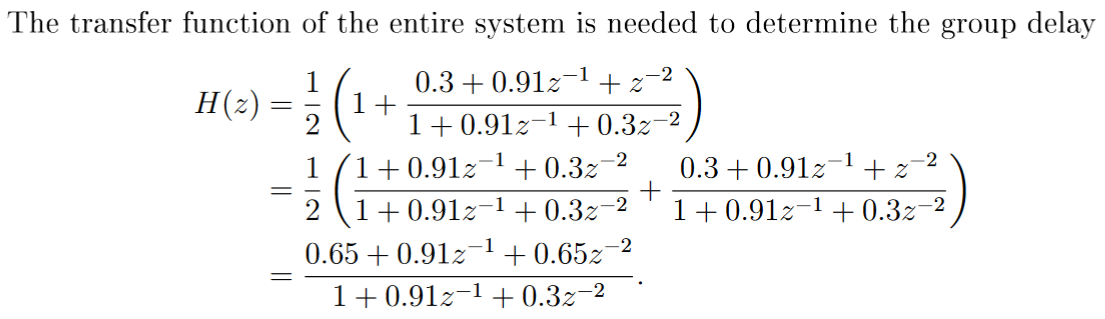

The group delay is then found using Matlab:

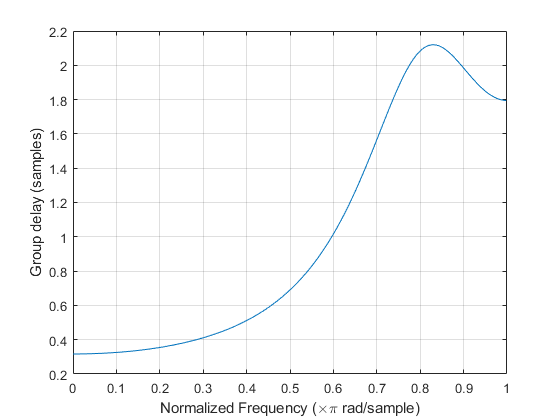

grpdelay([0.65 0.91 0.65],[1 0.91 0.3])

From which it is seen that the group delay at $\omega =\frac{\pi }{4}$ is 0.3788.

For completeness, the performance of the notch �lter can be plotted with freqz.

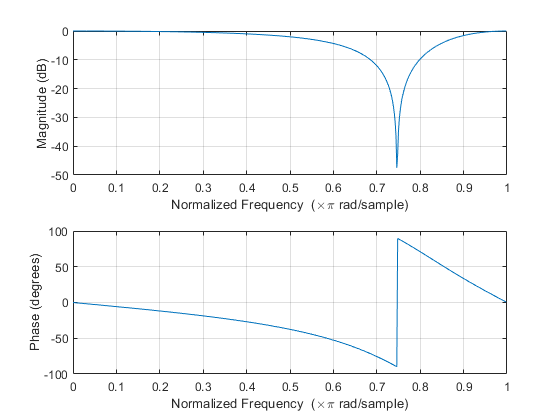

freqz([0.65 0.91 0.65],[1 0.91 0.3])

## Exam 2017 Problem 2: Lattice Structures

Many different lattice structure have been investigated over the years, often tailored to specific requirements. One particular example is based on minimizing hardware requirements and uses only one multiplication per stage. The structure of the *m*’th stage of a one-multiplier lattice filter is shown below. The input and output is connected as for standard all-pole filters.

        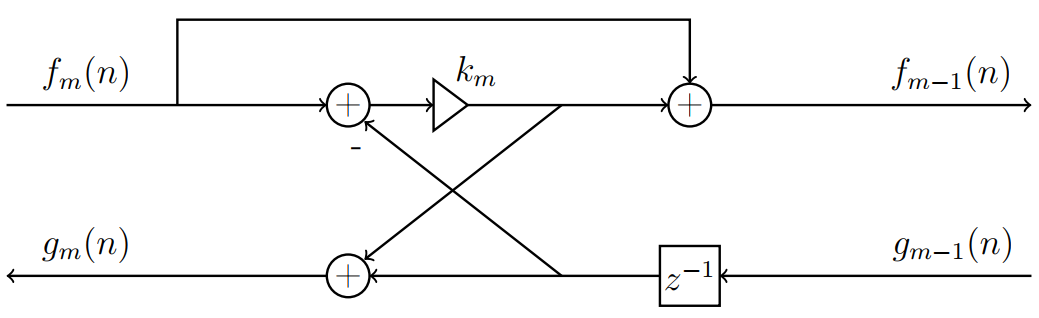

clear variables;

### 1) Determine the two equations relating outputs to inputs

        
$$f_{m-1} \left(n\right)=f_m \left(n\right)+k_m \left(f_m \left(n\right)-g_{m-1} \left(n\right)\right)$$


                    
$$=f_m \left(n\right)+k_m f_m \left(n\right)-k_m g_{m-1} \left(n-1\right)$$


                    
$$=\left(1+k_m \right)f_m \left(n\right)-k_m g_{m-1} \left(n-1\right)$$


        
$$g_m \left(n\right)=g_{m-1} \left(n-1\right)+k_m \left(f_m \left(n\right)-g_{m-1} \left(n\right)\right)$$


                  
$$=g_{m-1} \left(n-1\right)+k_m f_m \left(n\right)-k_m g_{m-1} \left(n\right)$$


                  
$$=k_m f_m \left(n\right)+\left(1-k_m \right)g_{m-1} \left(n-1\right)$$


### 2) When is the first non-zero sample observed at the output?

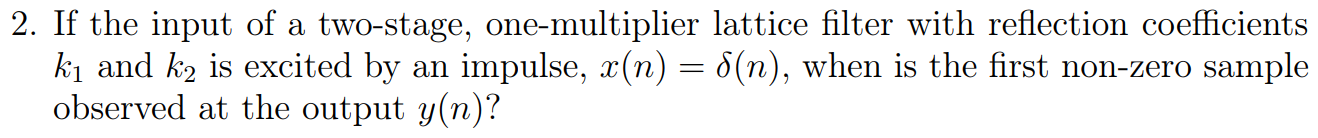

The two-stage, one multiplier lattice looks like this:

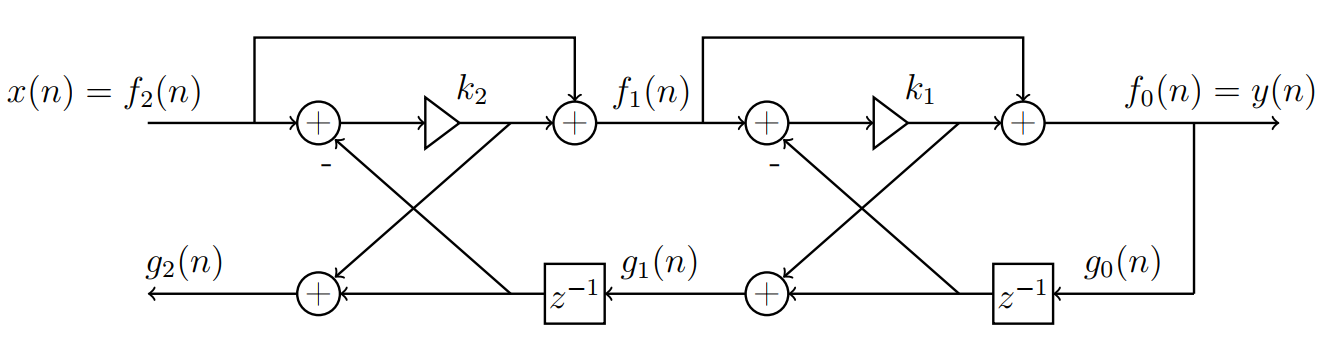

We found that the equation relating output to input is:

        
$$f_{m-1} \left(n\right)=\left(1+k_m \right)f_m \left(n\right)-k_m g_{m-1} \left(n-1\right)$$


Since we want the first output, we do not concern ourselves with the $g_{m-1} \left(n-1\right)$.

First, we compute $f_1 \left(n\right)$:

        
$$f_1 \left(n\right)=\left(1+k_2 \right)f_2 \left(n\right)=\left(1+k_2 \right)x\left(n\right)$$


Next, we compute $f_0 \left(n\right)$:

        
$$f_0 \left(n\right)=\left(1+k_1 \right)f_1 \left(n\right)=\left(1+k_1 \right)\left(1+k_2 \right)x\left(n\right)=y\left(n\right)$$


Since there is a direct path without any delays from input $x\left(n\right)$ to the output $y\left(n\right)$, the first non-zero sample appears instantaneously at the output. 

        
$$y\left(n\right)=\left(1+k_1 \right)\left(1+k_2 \right)x\left(n\right)$$


### 3) Calculate the transfer function for a one-stage lattice filter

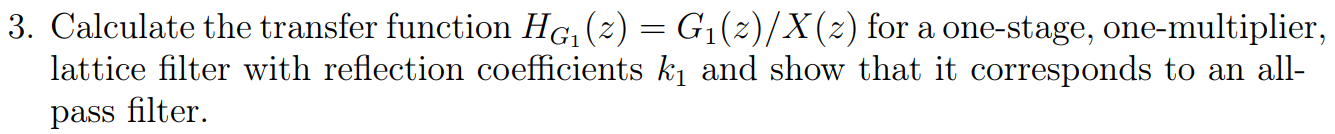

The one-stage, one multiplier lattice looks like this.  

        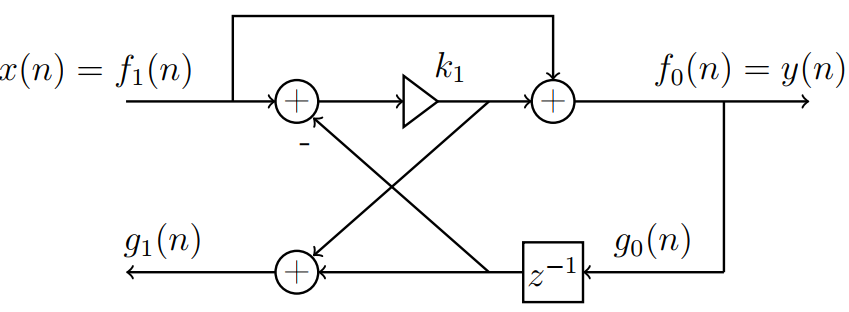

The equations relating the inputs and outputs are:

        
$$f_0 \left(n\right)=\left(1+k_1 \right)f_1 \left(n\right)-k_1 g_0 \left(n-1\right)$$


        
$$g_1 \left(n\right)=k_1 f_1 \left(n\right)+\left(1-k_1 \right)g_0 \left(n-1\right)$$


To calculate transfer functions, the two equations are first *z*-transformed:

        $F_0 \left(z\right)=\left(1+k_1 \right)F_1 \left(z\right)-k_1 z^{-1} G_0 \left(z\right)$  Eq. (1)

        $G_1 \left(z\right)=k_1 F_1 \left(z\right)+\left(1-k_1 \right)z^{-1} G_0 \left(z\right)$  Eq. (2)

We know that $F_1 \left(z\right)=X\left(z\right)$ and $F_0 \left(z\right)=G_0 \left(z\right)=Y\left(z\right)$. 

We use the identity $F_0 \left(z\right)=G_0 \left(z\right)$ to rewrite our Eq. (1):

        
$$G_0 \left(z\right)=\left(1+k_1 \right)F_1 \left(z\right)-k_1 z^{-1} G_0 \left(z\right)$$


        
$$G_0 \left(z\right)+k_1 z^{-1} G_0 \left(z\right)=\left(1+k_1 \right)F_1 \left(z\right)$$


        
$$\left(1+k_1 z^{-1} \right)G_0 \left(z\right)=\left(1+k_1 \right)F_1 \left(z\right)$$


        
$$G_0 \left(z\right)=\frac{\left(1+k_1 \right)F_1 \left(z\right)}{1+k_1 z^{-1} }$$


Substitutde the new expression into Eq. (2)

        
$$G_1 \left(z\right)=k_1 F_1 \left(z\right)+\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }F_1 \left(z\right)$$


We know that $F_1 \left(z\right)=X\left(z\right)$:

        
$$G_1 \left(z\right)=k_1 X\left(z\right)+\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }X\left(z\right)$$


        
$$G_1 \left(z\right)=X\left(z\right)\left(k_1 +\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }\right)$$


        
$$\frac{G_1 \left(z\right)}{X\left(z\right)}=k_1 +\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }$$


        
$$\frac{G_1 \left(z\right)}{X\left(z\right)}=\frac{k_1 \left(1+k_1 z^{-1} \right)}{1+k_1 z^{-1} }+\frac{\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }$$


        
$$\frac{G_1 \left(z\right)}{X\left(z\right)}=\frac{k_1 \left(1+k_1 z^{-1} \right)+\left(1-k_1 \right)\left(1+k_1 \right)z^{-1} }{1+k_1 z^{-1} }$$


syms k z
expand(k*(1+k*z)+(1-k)*(1+k)*z)

        
$$\frac{G_1 \left(z\right)}{X\left(z\right)}=\frac{k_1 +z^{-1} }{1+k_1 z^{-1} }$$


An allpass filter has the form:

        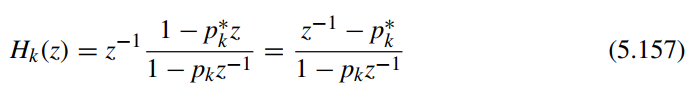

Higher order allpass systems can be obtained by cascading multiple first-order sections, as  

        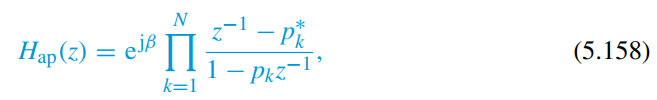

## Functions

function [k,G] = fir2lat(h)
% Converts FIR filter coefficients to lattice coefficients.
% From Figure 9.24 (p. 514)
    G = h(1); 
    a = h/G;
    M = length(h)-1; 
    k(M) = a(M+1);
    for m = M:-1:2
        b = fliplr(a);
        a = (a-k(m)*b)/(1-k(m)^2); a = a(1:m);
        k(m-1) = a(m);
    end
end


function [h] = lat2fir(k, G)
% Converts lattice coefficients to FIR filter coefficients.
% From Figure 9.25 (p. 515)
    a = 1; 
    b = 1; 
    M = length(k);
    for m = 1:1:M
        a = [a,0]+k(m)*[0,b];
        b = fliplr(a);
    end
    h = G*a;
end


function [y] = azlatfilt(k, x, G)
% AZLATFILT      Filters x with an all-zero lattice filter with
%                coefficients k. From Figure 9.26 (p 515)

    M = length(k); 
    
    % Create an array for the sequence f_m[n]
    f = zeros(1,M); 
    
    % Create an array for the sequence g_m[n]
    g = f;
    
    % Create an array for the sequence g_m[n-1]
    oldg = zeros(1,M);
    
    % Keeps track of x[n-1]
    oldx = 0;
    x = G*x; 
    y = zeros(size(x));
    
    for n=1:length(x)
        % Compute f1[n] = x[n] + k1x[n-1] -> Equation (9.57a)
        f(1) = x(n)+k(1)*oldx;
        
        % Compute g1[n] = k1x[n] + x[n-1] -> Equation (9.57b)
        g(1) = k(1)*x(n)+oldx;
        oldx = x(n);
        for m = 2:M
            % Compute: fm[n] = fm?1[n] + km gm?1[n ? 1] -> Equation (9.55a)
            f(m) = f(m-1)+k(m)*oldg(m-1);
            
            % Compute: gm[n] = km fm?1[n] + gm?1[n ? 1] -> Equation (9.55b)
            g(m) = k(m)*f(m-1)+oldg(m-1);
            
            % Delay
            oldg(m-1) = g(m-1);
        end
        
        % y[n] = fM[n] -> Equation (9.56b)
        y(n) = f(M);
    end
end

function y = aplatfilt(k,G,x)
% All-pole Lattice Filter Implementation
% From Figure 9.28 

    M = length(k); g = zeros(1,M); f = g;
    oldy = 0; x = G*x; y = zeros(size(x));
    for n = 1:length(x)
        f(M) = x(n);
        for i = 1:M-1
            m = M+1-i;
            f(m-1) = f(m)-k(m)*g(m-1);
            g(m) = k(m)*f(m-1)+g(m-1);
        end
        y(n) = f(1)-k(1)*oldy;
        g(1) = k(1)*y(n)+oldy;
        oldy = y(n);
    end
end
